clc
clear all

% Monte Carlo SST & d18Osw estimations

n = 2581;
TSST = readtable('SST.xlsx');

TSSTC = readtable('SSTA.xlsx','Sheet','SWIOSSTA');
TSSS = readtable('SSS.xlsx','Sheet','SSS 5m');

SODA_centred = TSSS.SODA-mean(TSSS.SODA,'omitnan');
IAP_centred = TSSS.IAP - mean(TSSS.IAP,'omitnan');
EN4_centred = TSSS.EN4 - mean(TSSS.EN4,'omitnan');
TSrCa = readtable('monthly raw data.xlsx','Sheet','SrCa');

Td18O = readtable('monthly raw data.xlsx','Sheet','d18O');

AER = readtable('monthly raw data.xlsx','Sheet','AER');

MC = readtable('monthly reconsMC.xlsx','VariableNamingRule','preserve','Sheet','84slope');
coralSST_centred = MC.SST;
coralSST_centred_l=MC.("2.5cl");
coralSST_centred_u=MC.("97.5cl");
coralSST_centred_l2=MC.("16cl");
coralSST_centred_u2=MC.("84cl");
errordate = vertcat(MC.Date,flipud(MC.Date));
errSST_MC90 = vertcat(coralSST_centred_u,flipud(coralSST_centred_l));
errSST_MC68 = vertcat(coralSST_centred_u2,flipud(coralSST_centred_l2));

SrCa_centred = TSrCa.SrCa - mean(TSrCa.SrCa,'omitnan');
d18O_centred = Td18O.d18O - mean(Td18O.d18O,'omitnan');

ERSSTv5_centred = TSST.ERSSTv5 - mean(TSST.ERSSTv5(n:end),'omitnan');
HadISST1_centred =TSST.HadISST - mean(TSST.HadISST(n:end),'omitnan');

TSSTC.BMerr90 = (coralSST_centred_u - coralSST_centred_l)/2;
TSSTC.BMerr68 = (coralSST_centred_u2 - coralSST_centred_l2)/2;
TSSTC.Mon = categorical(TSSTC.Mon);

Tsummer = vertcat(TSSTC((TSSTC.Mon=='1'),:),TSSTC((TSSTC.Mon=='2'),:),TSSTC((TSSTC.Mon=='3'),:),TSSTC((TSSTC.Mon=='12'),:));
Tsummer = sortrows(Tsummer,2);

Twinter = vertcat(TSSTC((TSSTC.Mon=='6'),:),TSSTC((TSSTC.Mon=='7'),:),TSSTC((TSSTC.Mon=='8'),:),TSSTC((TSSTC.Mon=='9'),:));
Twinter = sortrows(Twinter,2);
Twinter = Twinter(3:1342,:);

gamma1 = -0.22; %average slope of d18O - SST
d18Osw_c_HadISST1 = d18O_centred - gamma1*HadISST1_centred;
d18Osw_c_ERSSTv5 = d18O_centred - gamma1*ERSSTv5_centred;

d18Osw_centred = MC.d18Osw;
d18Osw_centred_l =MC.("2.5cl_1");
d18Osw_centred_u =MC.("97.5cl_1");
d18Osw_centred_l2 =MC.("16cl_1");
d18Osw_centred_u2 =MC.("84cl_1");
errordate = vertcat(MC.Date,flipud(MC.Date));
errd18Osw_MC95 = vertcat(d18Osw_centred_u,flipud(d18Osw_centred_l));
errd18Osw_MC68 = vertcat(d18Osw_centred_u2,flipud(d18Osw_centred_l2));

ans = -4.4858

% Annual mean Nov-Dec 
gap = (4:12:4024)';
yr = (1672:2006)';

ASSTC = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=TSSTC.BM84(gap(i):(gap(i+1)-1));
    ASSTC(i) = mean(t,'omitnan');
i=i+1;
end

ASSTC_Err90 = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=TSSTC.BMerr90(gap(i):(gap(i+1)-1));
    ASSTC_Err90(i) = rms(t,'omitnan');
i=i+1;
end

ASSTC_Err68 = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=TSSTC.BMerr68(gap(i):(gap(i+1)-1));
    ASSTC_Err68(i) = rms(t,'omitnan');
i=i+1;
end

AICOADS = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=TSSTC.ICOADS(gap(i):(gap(i+1)-1));
    if sum(isnan(t))>6
       AICOADS(i) = mean(t,'omitnan');
    else
       AICOADS(i) = mean(t);
    end
i=i+1;
end

AERA = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=AER.AER(gap(i):(gap(i+1)-1));
    AERA(i) = mean(t,'omitnan');
i=i+1;
end


Ad18Osw = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=d18Osw_centred(gap(i):(gap(i+1)-1));
    Ad18Osw(i) = mean(t,'omitnan');
i=i+1;
end


Ad18Osw2 = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=d18Osw_c_HadISST1(gap(i):(gap(i+1)-1));
    Ad18Osw2(i) = mean(t,'omitnan');
i=i+1;
end


Ad18Osw3 = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=d18Osw_c_ERSSTv5(gap(i):(gap(i+1)-1));
    Ad18Osw3(i) = mean(t,'omitnan');
i=i+1;
end

yr_s = (1672:2007)';
gap = (1:4:1345)';


summerSSTC = zeros(336,1);
for i=1:size(yr_s,1);
    t=Tsummer.BM84(gap(i):(gap(i+1)-1));
    summerSSTC(i) = mean(t,'omitnan');
i=i+1;
end

summerSSTCerror90 = zeros(336,1);
for i=1:size(yr_s,1);
    t=Tsummer.BMerr90(gap(i):(gap(i+1)-1));
    summerSSTCerror90 (i) = rms(t,'omitnan');
i=i+1;
end

summerSSTCerror68 = zeros(336,1);
for i=1:size(yr_s,1);
    t=Tsummer.BMerr68(gap(i):(gap(i+1)-1));
    summerSSTCerror68 (i) = rms(t,'omitnan');
i=i+1;
end


summerICOADS = zeros(size(yr,1),1);
for i=1:size(yr_s,1);
    t=Tsummer.ICOADS(gap(i):(gap(i+1)-1));
    if sum(~isnan(t))>2
       summerICOADS(i) = mean(t,'omitnan');
    else
       summerICOADS(i) = mean(t);
    end
i=i+1;
end

% 
% summeruwind20CV = zeros(336,1);
% for i=1:size(yr_s,1);
%     t=Tsummer.uwind20CV(gap(i):(gap(i+1)-1));
%     summeruwind20CV(i) = mean(t,'omitnan');
% i=i+1;
% end
% 
% summeruwind20CV850 = zeros(336,1);
% for i=1:size(yr_s,1);
%     t=Tsummer.uwind20CV850(gap(i):(gap(i+1)-1));
%     summeruwind20CV850(i) = mean(t,'omitnan');
% i=i+1;
% end
% 

gap = (1:4:1341)';
yr_w = (1672:2006)';


winterSSTC = zeros(335,1);
for i=1:size(yr_w,1);
    t=Twinter.BM84(gap(i):(gap(i+1)-1));
    winterSSTC(i) = mean(t,'omitnan');
i=i+1;
end

winterSSTCerror90 = zeros(335,1);
for i=1:size(yr_w,1);
    t=Twinter.BMerr90(gap(i):(gap(i+1)-1));
    winterSSTCerror90(i) = rms(t,'omitnan');
i=i+1;
end

winterSSTCerror68 = zeros(335,1);
for i=1:size(yr_w,1);
    t=Twinter.BMerr68(gap(i):(gap(i+1)-1));
    winterSSTCerror68(i) = rms(t,'omitnan');
i=i+1;
end

winterICOADS = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=Twinter.ICOADS(gap(i):(gap(i+1)-1));
    if sum(~isnan(t))>2
       winterICOADS(i) = mean(t,'omitnan');
    else
       winterICOADS(i) = mean(t);
    end
i=i+1;
end



summerSSTCerror90_2 = vertcat(summerSSTC+summerSSTCerror90,flipud(summerSSTC-summerSSTCerror90));
summerSSTCerror68_2 = vertcat(summerSSTC+summerSSTCerror68,flipud(summerSSTC-summerSSTCerror68));
patch_date_summer = vertcat(yr_s,flipud(yr_s));

winterSSTCerror90_2 = vertcat(winterSSTC+winterSSTCerror90,flipud(winterSSTC-winterSSTCerror90));
winterSSTCerror68_2 = vertcat(winterSSTC+winterSSTCerror68,flipud(winterSSTC-winterSSTCerror68));
patch_date_winter = vertcat(yr_w,flipud(yr_w));

patch_date_annual = vertcat(yr,flipud(yr));
ASSTCerror90_2 = vertcat(ASSTC+ASSTC_Err90,flipud(ASSTC-ASSTC_Err90));
ASSTCerror68_2 = vertcat(ASSTC+ASSTC_Err68,flipud(ASSTC-ASSTC_Err68));

ASSTC(45) = nan;
ASSTC(60:62) =nan;
summerSSTC(45) = nan;
summerSSTC(60:62) =nan;
winterSSTC(45) = nan;
winterSSTC(60:62) =nan;

[ASSTC,~] = fillmissing(ASSTC,"linear","SamplePoints",yr); %fill gap 
[summerSSTC,~] = fillmissing(summerSSTC,"linear","SamplePoints",yr_s); %fill gap 
[winterSSTC,~] = fillmissing(winterSSTC,"linear","SamplePoints",yr_w); %fill gap 

a = max(ASSTC(1:65))-min(ASSTC(1:65))

a = 1.6504

s = max(summerSSTC(1:65))-min(summerSSTC(1:65))

s = 1.6833

w = max(winterSSTC(1:65))-min(winterSSTC(1:65))

w = 1.7121

m=216;
fitlm(yr_s(216:end),summerSSTC(216:end))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE         tStat       pValue  
                   _________    _________    _______    __________

    (Intercept)      -14.989        2.285    -6.5598    1.4644e-09
    x1             0.0074604    0.0011734     6.3578    3.9331e-09


Number of observations: 121, Error degrees of freedom: 119
Root Mean Squared Error: 0.451
R-squared: 0.254,  Adjusted R-Squared: 0.247
F-statistic vs. constant model: 40.4, p-value = 3.93e-09

0.0074604*121

ans = 0.9027

0.0011734*1*121

ans = 0.1420

fitlm(yr_w(216:end),winterSSTC(216:end))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE         tStat       pValue  
                   _________    _________    _______    __________

    (Intercept)       -15.36       2.0878    -7.3572    2.7192e-11
    x1             0.0076623    0.0010724      7.145    8.0373e-11


Number of observations: 120, Error degrees of freedom: 118
Root Mean Squared Error: 0.407
R-squared: 0.302,  Adjusted R-Squared: 0.296
F-statistic vs. constant model: 51.1, p-value = 8.04e-11

0.0076623*121

ans = 0.9271

0.0010724*1*121

ans = 0.1298

fitlm(yr_w(216:end),ASSTC(216:end))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE         tStat       pValue  
                   _________    __________    _______    __________

    (Intercept)      -14.863        1.7792    -8.3534    1.4787e-13
    x1             0.0073971    0.00091391     8.0938     5.855e-13


Number of observations: 120, Error degrees of freedom: 118
Root Mean Squared Error: 0.347
R-squared: 0.357,  Adjusted R-Squared: 0.352
F-statistic vs. constant model: 65.5, p-value = 5.85e-13

0.0073971*121

ans = 0.8950

0.00091391*1*121

ans = 0.1106

# figure 5.S1

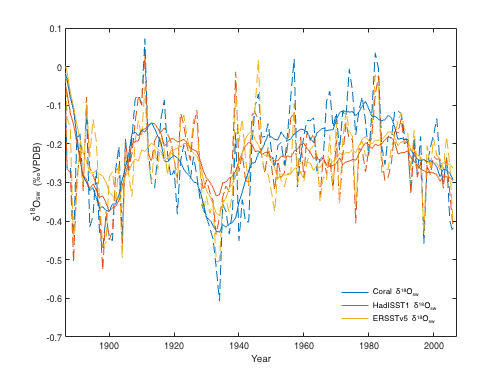

close
clf('reset')

plot(yr,Ad18Osw,'LineStyle','--')
hold on 
plot(yr,Ad18Osw2,'LineStyle','--')
plot(yr,Ad18Osw3,'LineStyle','--')


plot(yr,movmean(Ad18Osw,10),'color',[0 0.4470 0.7410],'LineWidth',1)
plot(yr,movmean(Ad18Osw2,10),'color',[0.8500 0.3250 0.0980],'LineWidth',1)
plot(yr,movmean(Ad18Osw3,10),'color',[0.9290 0.6940 0.1250],'LineWidth',1)

set(gca,'xlim',[1886.583 2007])
%set(gca,'ylim',[-1.2 1.2])
ylabel('\delta^{18}O_{sw} (‰VPDB)')
lg = legend('','','','Coral \delta^{18}O_{sw}','HadISST1 \delta^{18}O_{sw}','ERSSTv5 \delta^{18}O_{sw}');
set(lg,'box','off','Location','best')
box on 
xlabel('Year')


% ncdisp("")
% ncfile = '' ;
% clf
% long = ncread(ncfile,'lon') ;nx = length(long) ;
% lat = ncread(ncfile,'lat') ; ny = length(lat) ;
% time = ncread(ncfile,'time') ; nt = length(time) ;
% Corr = ncread(ncfile,'corr') ;
% Pro = ncread(ncfile,'prob') ;
% [X,Y] = meshgrid(long,lat);
% pcolor(X,Y,Corr(:,:,1)') ;
% shading interp ;
% title(sprintf('Annual mean'))
% pause(0.1)
% colorbar;
% [idx,idy] = find(Pro>0.1);
% sigX = long(idx);
% sigY = lat(idy);
% hold on
% plot(sigX,sigY,'.');


# Figure 5.5

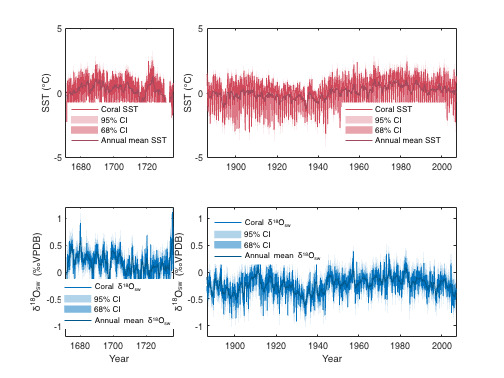

close
clf ('reset')
subplot(2,3,1)
hold on
plot(MC.Date,coralSST_centred,'linewidth',1,'color',[0.82 0.29 0.36])
patch(errordate,errSST_MC90,[0.82 0.29 0.36],'Edgecolor','none','Facealpha',0.3)
patch(errordate,errSST_MC68,[0.82 0.29 0.36],'Edgecolor','none','Facealpha',0.5)
plot(MC.Date,movmean(coralSST_centred,13),'color',[0.62 0.29 0.36],LineWidth=1)
set(gca,'xlim',[1671 1736])
set(gca,'ylim',[-5 5])
ylabel('SST (°C)')
lg = legend('Coral SST','95% CI','68% CI','Annual mean SST','location','northeast');
set(lg,'box','off','Location','best')
box on 

subplot(2,3,[2 3])
hold on
plot(MC.Date,coralSST_centred,'linewidth',1,'color',[0.82 0.29 0.36])
patch(errordate,errSST_MC90,[0.82 0.29 0.36],'Edgecolor','none','Facealpha',0.3)
patch(errordate,errSST_MC68,[0.82 0.29 0.36],'Edgecolor','none','Facealpha',0.5)
plot(MC.Date,movmean(coralSST_centred,13),'color',[0.62 0.29 0.36],LineWidth=1)
set(gca,'xlim',[1886 2007])
set(gca,'ylim',[-5 5])
ylabel('SST (°C)')
lg = legend('Coral SST','95% CI','68% CI','Annual mean SST','location','northeast');
set(lg,'box','off','Location','best')
box on 


subplot(2,3,4)
hold on
plot(MC.Date,d18Osw_centred,'linewidth',1,'color',[0 0.4470 0.7410])
patch(errordate,errd18Osw_MC95,[0 0.4470 0.7410],'Edgecolor','none','Facealpha',0.3)
patch(errordate,errd18Osw_MC68,[0 0.4470 0.7410],'Edgecolor','none','Facealpha',0.5)
plot(MC.Date,movmean(d18Osw_centred,13),'linewidth',1,'color',[0 0.3470 0.5410])
set(gca,'xlim',[1671 1736.583])
set(gca,'ylim',[-1.2 1.2])
ylabel('\delta^{18}O_{sw} (‰VPDB)')
lg = legend('Coral \delta^{18}O_{sw}','95% CI','68% CI','Annual mean \delta^{18}O_{sw}');
set(lg,'box','off','Location','best')
box on 
xlabel('Year')

subplot(2,3,[5 6])
hold on
plot(MC.Date,d18Osw_centred,'linewidth',1,'color',[0 0.4470 0.7410])
patch(errordate,errd18Osw_MC95,[0 0.4470 0.7410],'Edgecolor','none','Facealpha',0.3)
patch(errordate,errd18Osw_MC68,[0 0.4470 0.7410],'Edgecolor','none','Facealpha',0.5)
plot(MC.Date,movmean(d18Osw_centred,13),'linewidth',1,'color',[0 0.3470 0.5410])
set(gca,'xlim',[1886.583 2007])
set(gca,'ylim',[-1.2 1.2])
ylabel('\delta^{18}O_{sw} (‰VPDB)')
lg = legend('Coral \delta^{18}O_{sw}','95% CI','68% CI','Annual mean \delta^{18}O_{sw}');
set(lg,'box','off','Location','best')
box on 
xlabel('Year')

% max(d18Osw_centred(n:end))

ans = 0.4425

% min(d18Osw_centred(n:end))

ans = -0.9214

% mean(d18Osw_centred(n:end))

ans = -0.2369

% m = 781;
% max(d18Osw_centred(1:m))

ans = 1.1151

% min(d18Osw_centred(1:m))

ans = -0.6474

% mean(d18Osw_centred(1:m))

ans = 0.1690